clc;clear;close all;
workingPath = 'D:\deeplearning - diffraction'

workingPath = 'D:\deeplearning - diffraction'

CheckpointPath = '.\checkpoint'

CheckpointPath = '.\checkpoint'

gpuDevice(1);
isretrain = 0;
cd(workingPath)

产生数据集

pic_path ='D:\deeplearning - diffraction\diffraction\Three_write';
boundary_path = 'D:\deeplearning - diffraction\table';
diffractionDataset=Generate_train(pic_path,boundary_path);
cd(workingPath)

read picture

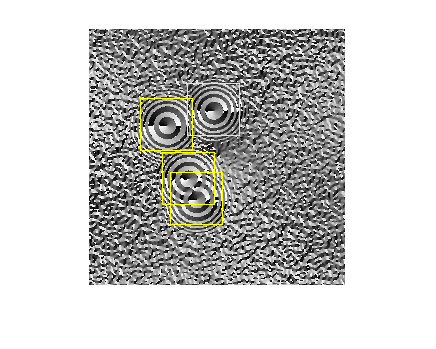

I = imread(diffractionDataset.imageFilename{70});
I = insertShape(I, 'Rectangle', diffractionDataset.boundary_cell{70});
% I = imresize(I,3);
figure
imshow(I)

分割数据集

rng(0);
shuffledIdx = randperm(height(diffractionDataset));
idx = floor(0.5 * height(diffractionDataset));
trainingData = diffractionDataset(shuffledIdx(1:idx),:);
testData = diffractionDataset(shuffledIdx(idx+1:end),:);



%'ValidationData',testData,...


建立yolov2

imageSize = [256,256,3];
numClasses =1;
anchorBoxes = [
   78   78
   37   37
    53    53
   72   72
   91   91
   110   110
];
network  = inceptionresnetv2();
featureLayer = 'conv_7b_ac';
% reorgLayer = 'activation_47_relu';


% Create the YOLO v2 object detection network. 
lgraph = yolov2Layers(imageSize,numClasses,anchorBoxes,network,featureLayer);%,'ReorglayerSource',reorgLayer);

%迭代器参数
options = trainingOptions('adam', ...     %使用SGD
    'MaxEpochs', 150, ...                   %最大迭代次数
    'MiniBatchSize',16, ...               %BatchSize
    'InitialLearnRate', 3e-4, ...         %初始学习率
    'CheckpointPath', CheckpointPath,...  %检查点
    "Verbose",true,...
    'VerboseFrequency',100,...
    "LearnRateSchedule","piecewise",...
    "LearnRateDropPeriod",40,...          %每20epoch衰减学习率
    'L2Regularization',0.0001,...
    'Shuffle','every-epoch',...
    'ExecutionEnvironment',"gpu");  %指定多GPU

开始训练

if isretrain<1
    [detector, info] = trainYOLOv2ObjectDetector(trainingData,lgraph,options);
else
    str = [CheckpointPath,'\yolov2_checkpoint__8880__2019_11_09__18_35_07.mat']
    retrain_data = load(str);
    checkpoint = retrain_data.detector;
    shuffledIdx = randperm(height(testData));
    idx = floor(0.4 * height(testData));
    trainingData1 = testData(shuffledIdx(1:idx),:);
    [detector, info] = trainYOLOv2ObjectDetector(trainingData,checkpoint,options);
end

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* boundary_cell

Checking training data...done.
正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　小批量损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０７　｜　　　　　　　２．８９　｜　　　　　８．３　｜　　０．０００３　｜
｜　　　２　｜　　１００　｜　　　　　００：０９：５２　｜　　　　　　　０．５７　｜　　　　　０．３　｜　　０．０００３　｜
｜　　　３　｜　　２００　｜　　　　　００：１９：４２　｜　　　　　　　０．４４　｜　　　　　０．２　｜　　０．０００３　｜
｜　　　４　｜　　３００　｜　　　　　００：２９：３８　｜　　　　　　　０．４４　｜　　　　　０．２　｜　　０．０００３　｜
｜　　　５　｜　　４００　｜　　　　　００：３９：２５　｜　　　　　　　０．３６　｜　　　　　０．１　｜　　０．０００３　｜
｜　　　６　｜　　５００　｜　　　　　００：４９：１２　｜　　　　　　　０．３７　｜　　　　　０．１　｜　　０．０００３　｜
｜　　　７　｜　　６００　｜　　　　　００：５８：５７　｜　　　　　　　０．３４　｜　　　　　０．１　｜　　０．０００３　｜
｜　　　８　｜　　７００　｜　　　　　０１：０８：３１　｜　　　　　　　０．３４　｜　　　　　０．１　｜　　０．０００３　｜
｜　　　９　｜　　８００　｜　　　　　０１：１８：０２　｜　　　　　　　０．

输出结果

I = imread(testData.imageFilename{randi(1000)});

% Run the detector.
[bboxes,scores] = detect(detector,I);
save('yolov2detector.mat','detector','info')
% Annotate detections in the image.
I = insertObjectAnnotation(I,'rectangle',bboxes,scores);
figure
imshow(I)

评估

numImages = height(testData);
results = table('Size',[numImages 3],...
    'VariableTypes',{'cell','cell','cell'},...
    'VariableNames',{'Boxes','Scores','Labels'});

% Run detector on each image in the test set and collect results.
for i = 1:numImages
    
    % Read the image.
    I = imread(testData.imageFilename{i});
    
    % Run the detector.
    [bboxes, scores, labels] = detect(detector, I);
    
    % Collect the results.
    % Collect the results.
    results.Boxes{i} = bboxes;
    results.Scores{i} = scores;
    results.Labels{i} = labels;
end
% Extract expected bounding box locations from test data.
expectedResults = testData(:, 2:end);


% Evaluate the object detector using Average Precision metric.
[ap, recall, precision] = evaluateDetectionPrecision(results, expectedResults);
% Plot precision/recall curve
figure
plot(recall,precision)
xlabel('Recall')
ylabel('Precision')
grid on
title(sprintf('Average Precision = %.2f', ap))
save('yolov2.mat','results','expectedResults')